# A thin rolling wheel(NO slip) **- Simulation with Simscape**

In this script we'll define numeric parameters needed to simulate the dynamics of the rolling wheel ... for a **Simscape Multibody** model of the wheel.  In our Simulink model we will compare the results produced by the Simscape model against the corresponding results produced by the Lagrangian and Newtonian derived models.

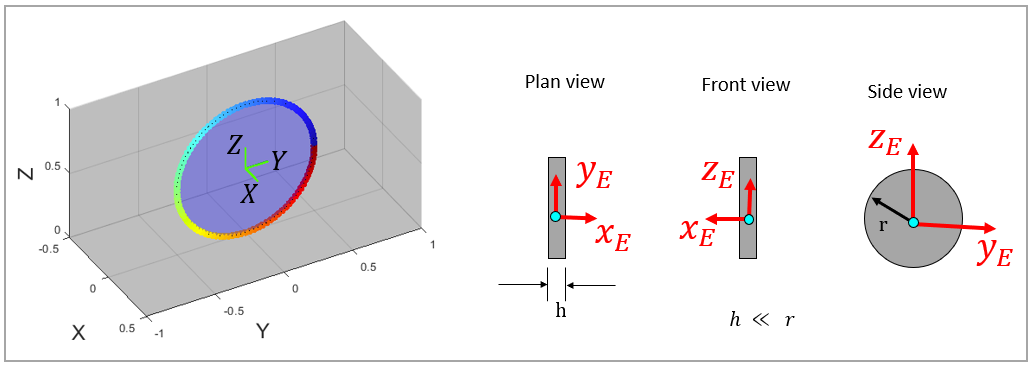

## The Euler angles 

Recall the Euler angle sequence used in the 2 previous derivations.   

- $R_{1Z}$ occurs  1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- $R_{2Y}$ occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- $R_{3X}$ occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

This Euler angle sequence is illustrated below

     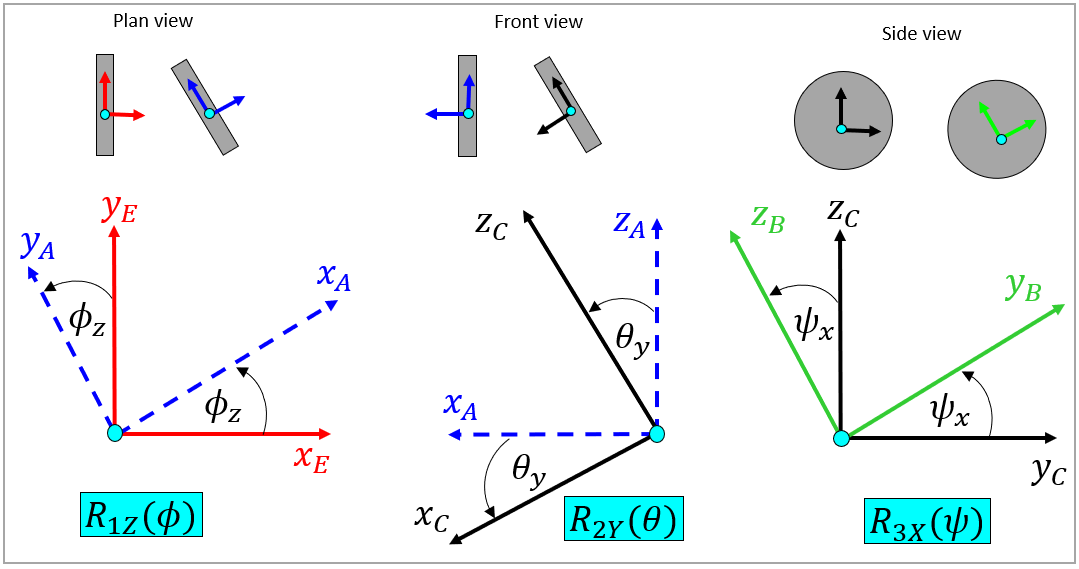   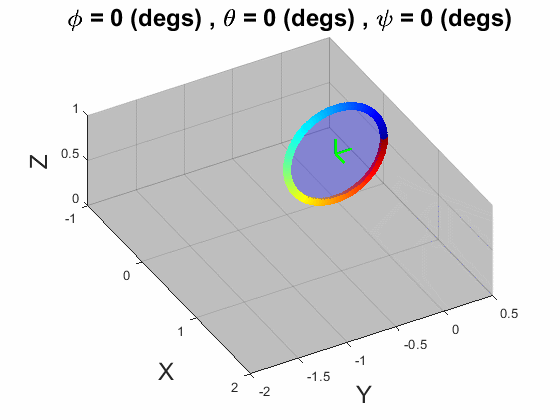

## The Model parameters: 

params_T.m   =  5;        % (kg)
params_T.g   =  9.80665;  % (m/sec^2)
params_T.r   =  0.5;      % (m)

tmp_Ig       = LOC_calc_Ig_for_this_disk(params_T.r, params_T.m);
params_T.I_A = tmp_Ig(1,1);  % (kg.m^2)  == the Axial       moment of Inertia  == I_xx
params_T.I_T = tmp_Ig(2,2);  % (kg.m^2)  == the Transverse  moment of Inertia  == I_yy == I_zz

Pack the inertia terms into the form(AND orientation) that our **Simscape model** needs:

params.I_mome_for_simscape = [tmp_Ig(2,2), tmp_Ig(3,3), tmp_Ig(1,1)];
params.I_prod_for_simscape = [0,0,0];

params_T

params_T = struct with fields:
      m: 5
      g: 9.8066
      r: 0.5000
    I_A: 0.6250
    I_T: 0.3125


## Define the INITIAL conditions

Here are some IC's needed by our Lagrangian and Newtonian models:

IC_T.phi       =  deg2rad(45*1);   % (rad)
IC_T.theta     =  deg2rad(20*1);   % (rad)
IC_T.psi       =  deg2rad(0);      % (rad)
IC_T.phi_dot   =  0;               % (rad/sec)
IC_T.theta_dot =  0;               % (rad/sec)
IC_T.psi_dot   = deg2rad(240);     % (rad/sec)

In our **Simscape** model we'll use a [**6-dof joint block**](matlab:  web(fullfile(docroot, 'physmod/sm/ref/6dofjoint.html'))) to allow the wheel to move, so let's create the IC variables for configuring this block

% ROTATIONAL pos and velocity ICs needed by the block
IC_T.rot_ang_ZYX   = [IC_T.phi,     IC_T.theta,     IC_T.psi];      % (rad)
IC_T.rot_vel_ZYX   = LOC_get_wB(IC_T.phi, IC_T.theta, IC_T.psi, IC_T.phi_dot, IC_T.theta_dot, IC_T.psi_dot); % (rad/sec)

And a few more IC's needed by our Lagrangian, Newtonian AND **Simscape** models:

% TRANSLATIONAL pos and velocity ICs of the CoM
tmp_vel_E_G        = LOC_calc_XYZ_G_vel(params_T.r, IC_T.phi, IC_T.theta, IC_T.psi, IC_T.phi_dot, IC_T.theta_dot, IC_T.psi_dot);
tmp_pos_E_G        = LOC_calc_XYZ_G_pos(params_T.r, IC_T.phi, IC_T.theta, IC_T.psi);

IC_T.x             = tmp_pos_E_G(1);    %  (m)
IC_T.y             = tmp_pos_E_G(2);    %  (m)
IC_T.z             = tmp_pos_E_G(3);    %  (m)
IC_T.x_dot         = tmp_vel_E_G(1);    %  (m/sec)
IC_T.y_dot         = tmp_vel_E_G(2);    %  (m/sec)
IC_T.z_dot         = tmp_vel_E_G(3);    %  (m/sec)

IC_T

IC_T = struct with fields:
            phi: 0.7854
          theta: 0.3491
            psi: 0
        phi_dot: 0
      theta_dot: 0
        psi_dot: 4.1888
    rot_ang_ZYX: [0.7854 0.3491 0]
    rot_vel_ZYX: [3×1 double]
              x: 0.1710
              y: 0
              z: 0.4698
          x_dot: 1.4810
          y_dot: -1.4810
          z_dot: 0


## Define the parameters for our contact friction model

Our Simscape model uses a [**Spatial Contact Force block**](matlab:  web(fullfile(docroot, 'physmod/sm/ref/spatialcontactforce.html'))) to model the contact interaction between the wheel and the floor.  Here are the parameters that we'll use for this componnet:

contact.Nf_stiff    = 1e5;   % (N/m) 
contact.Nf_damp     = 1e3;   % (N/(m/s))
contact.Nf_trwidth  = 1e-4;  % (m)
contact.Ff_costat   = 0.9;
contact.Ff_codyn    = 0.8;
contact.Ff_critvel  = 1e-4;  % (m/s) 

## Open the Simscape model

open_system('bh_rolling_wheel_sim_simscape')

# Local Subfunctions only beyond this point

### Compute Ig for a this disk

- REF:  "Vector mechanics for Engineers" - F.P,Beer, E.R.Jonston

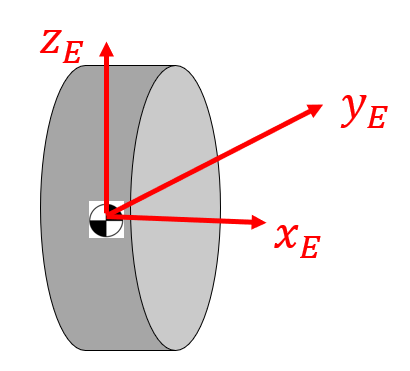

function Ig = LOC_calc_Ig_for_this_disk(r, m)

    Ig      = zeros(3);
    
    Ig(1,1) = 0.50 * m * r^2;  % Axial      inertia
    Ig(2,2) = 0.25 * m * r^2;  % Transverse inertia
    Ig(3,3) = 0.25 * m * r^2;  % Transverse inertia
end

Specify the translational velocity constraints

function v_E_G = LOC_calc_XYZ_G_vel(r, phi, theta, psi, phi_dot, theta_dot, psi_dot)

v_E_G = ...
    [  r*(psi_dot*sin(phi) + theta_dot*cos(phi)*cos(theta) - phi_dot*sin(phi)*sin(theta));
       r*(phi_dot*cos(phi)*sin(theta) - psi_dot*cos(phi) + theta_dot*cos(theta)*sin(phi));
      -r*theta_dot*sin(theta) ];

end

Specify the translational POSITION constraints

function pos_E_G = LOC_calc_XYZ_G_pos(r, phi, theta, psi)
    
    % compute G after phi and theta - assume E-frame origin is at GROUND
    xyz_col_E_before_roll = inv( LOC_get_RZ(phi) *  LOC_get_RY(theta)) * [0;0;r];
    
    % displacement in the C-frame is
    disp_C = [0; -(r * psi); 0];
    
    % so the components of this displacement in the E-frame are
    disp_E = inv( LOC_get_RY(theta) *  LOC_get_RZ(phi)) * disp_C;
    
    % add the displacement to the starting position
    pos_E_G = xyz_col_E_before_roll   + ...
              disp_E;

end

Define the passive Rotation matrix - $R_X \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_X \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RX(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1X'}, a, 'RADIANS');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Y \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Y \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RY(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Y'}, a, 'RADIANS');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Z \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Z \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RZ(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, a, 'RADIANS');
    R   = OBJ.get_R;
end

The angular velocity of the wheel in components of the B-frame:

function wB = LOC_get_wB(phi, theta, psi, phi_dot, theta_dot, psi_dot)

    wB = zeros(3,1);
    
    wB(1) = psi_dot                     - phi_dot*sin(theta);
    wB(2) = theta_dot*cos(psi)          + phi_dot*cos(theta)*sin(psi); 
    wB(3) = phi_dot*cos(psi)*cos(theta) - theta_dot*sin(psi);

end